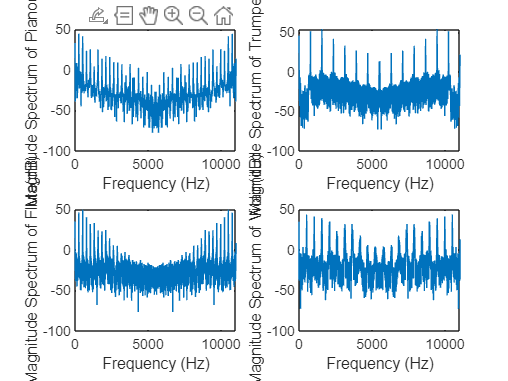

%prob1
[P,Fs ]= audioread("piano1.wav");
[T,Fs]= audioread("trumpet1.wav");
[F,Fs]= audioread("flute2.wav");
[V,Fs]= audioread("violin1.wav");

 n=0:Fs-1;
 t=1/Fs;
 fft_p=fft(P);
 N1=length(P);
 fp=(0:N1-1)*Fs/N1;
 subplot(2,2,1)
 plot(fp,db(abs(fft_p)))
 [m1,i1]= max(db(fft_p));
 xlabel("Frequency (Hz)")
 ylabel("Magnitude Spectrum of Piano(dB)")
 

 fft_t=fft(T);
 N2=length(T);
 ft=(0:N2-1)*Fs/N2;
 subplot(2,2,2)
 plot(ft,db(abs(fft_t)))
 [m2,i2]= max(db(fft_t));
 xlabel("Frequency (Hz)")
 ylabel("Magnitude Spectrum of Trumpet(dB)")
 

 fft_f=fft(F);
 N3=length(F);
 ff=(0:N3-1)*Fs/N3;
 subplot(2,2,3)
 plot(ff,db(abs(fft_f)))
 [m3,i3]= max(db(fft_f));
 xlabel("Frequency (Hz)")
 ylabel("Magnitude Spectrum of Flute(dB)")
 

 fft_v=fft(V);
 N4=length(V);
 fv=(0:N4-1)*Fs/N4;
 subplot(2,2,4)
 plot(fv,db(abs(fft_v)))
 [m4,i4]= max(db(fft_v));
 xlabel("Frequency (Hz)")
 ylabel("Magnitude Spectrum of Violin(dB)")

 disp("The fundamental frequency of Piano :")

The fundamental frequency of Piano :


 disp(fp(i1))

  261.6353



 disp("The fundamental frequency of Trumpet :")

The fundamental frequency of Trumpet :


 disp(ft(i2))

   1.5662e+03



 disp("The fundamental frequency of Flute:")

The fundamental frequency of Flute:


 disp(ff(i3))

  524.3338



 disp("The fundamental frequency of Violin :")

The fundamental frequency of Violin :


 disp(fv(i4))

  522.6397



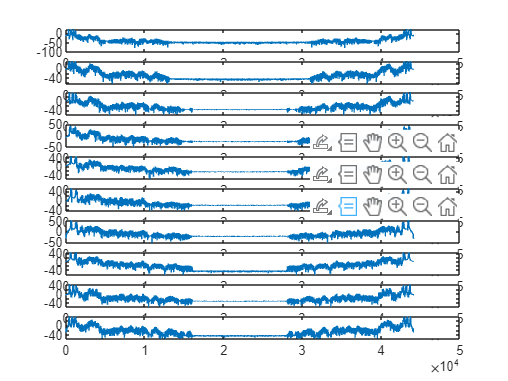

ans = 914

ans = 380

ans = 420

ans = 580

ans = 634

ans = 616

ans = 624

ans = 1288

ans = 482

ans = 404

% prob 3
 [o, Fs]= audioread("Opera.wav");
sound(o, Fs)
O= fft(o); 
f = Fs*(0:length(o)-1)/length(o); 
plot(f,db(abs(O)));
xlabel('Frequency (Hz)');
ylabel('Magnitude(dB)');
N = length(o)/10; 
 M = floor(length(o)/N); 
 for i = 1:M
     o_segment = o((i-1)*N+1:i*N);
     O_segment = fft(o_segment); 
     f_segment = Fs*(0:N-1)/N; 
     [m,j] = max(db(O_segment));
     f_segment(j)
     subplot(M,1,i)
     xlabel("Frequency(Hz)")
     ylabel("Amplitude(dB)")
     plot(f_segment,db(abs(O_segment)));
 end

% prob 2

% 1. Record a 3-second snippet of your whistling:
duration = 3; % seconds
fs = 44100; % sample rate
recObj = audiorecorder(fs, 16, 1); % 16-bit, mono

disp('Start whistling...')

Start whistling...


recordblocking(recObj, duration);
disp('Finished recording.');

Finished recording.


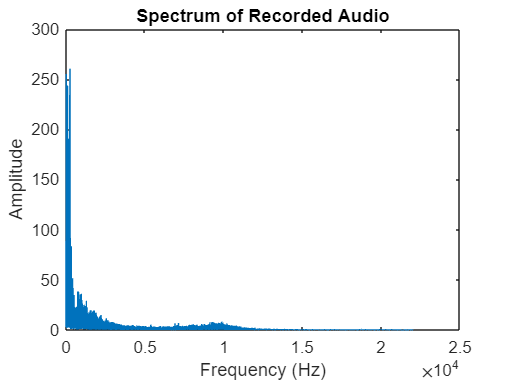


% 2. Plot the spectrum and find the fundamental frequency using peak picking:
audioData = getaudiodata(recObj);
N = length(audioData);
frequencies = linspace(0, fs/2, N/2);
spectrum = abs(fft(audioData));
spectrum = spectrum(1:N/2);

% Plot the spectrum
figure;
plot(frequencies, spectrum);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Spectrum of Recorded Audio');


% Find the fundamental frequency using peak picking
[pks, locs] = findpeaks(spectrum, 'MinPeakHeight', max(spectrum) * 0.2);
fundamentalFrequency = frequencies(locs(1));

disp(['Fundamental Frequency: ' num2str(fundamentalFrequency) ' Hz']);

Fundamental Frequency: 12.0002 Hz



% 3. Design a keylock:
referenceFrequency = 1200; % Enter the reference frequency from your whistle recording;
threshold = 0.05 * referenceFrequency; % 5% error threshold

% Compare the fundamental frequency with the reference
if abs(fundamentalFrequency - referenceFrequency) <= threshold
    disp('ACCESS GRANTED');
else
    disp('ACCESS DENIED');
end

ACCESS DENIED
